Specify the seaweed species in the following code by commenting out the rest.

clear all
%Seaweed = "Sargassum";
%Seaweed = "Laminaria"; %Japonica
%Seaweed = "Saccharina"; %sugar kelp
 Seaweed = "Macrocystis";
%Seaweed = "Ulva"; %Lactuca
%Seaweed = "Sugar cane bagasse";
%Seaweed = "Natural";

Specify whether the species is sunk naturally or artificially

Sinking = "Natural"

Sinking = "Natural"

%Sinking = "Forced"


Specify which of the three location you want to use by commenting out the rest

Location = "H9"

Location = "H9"

%Location = "SM7"
%Location = "W2"

Specify when you want the organic carbon flux to start and when you want it to end:

## Start and stop time organic carbon influx seaweed

a = 0.1; %introduction of Organic carbon flux in years
b = 1.1;%stoptime; % end organic carbon flux in years

The following loop create variables based on the species chosen, alter the time resolution in the location files in order to avoid errors

if Seaweed=="Sargassum" && Sinking == "Natural"
    disp(Seaweed)
    Focs=3.03;          %[mol/m2/a] flux of total organic carbon to the bottom (Hu et al., 2021; Gouvêa et al., 2020)
    Froc_s=Focs*0.03;   %[mol/m2/a] flux of refractory organic carbon to the bottom 
    Fsoc_s=Focs*0.27;   %[mol/m2/a] flux of slow-decay organic carbon to the bottom 
    Ffoc_s=Focs*0.70;   %[mol/m2/a] flux of fast-decay organic carbon to the bottom
    kfast_0s = 70 ;     % [/a] fast decay
    kslow_0s = 0.5;     % [/a] slow decay (0.0001 or 0.5 /yr?)
    RCs=537;            % C ratio for sargassum
    RNs=22;            % N ratio
    RPs=1;              % P ratio
elseif Seaweed=="Sargassum" && Sinking == "Forced"
    disp(Seaweed)
    Focs= 27.5*(365/3);% 3 days  %[mol/m2/a] flux of total organic carbon to the bottom (Hu et al., 2021; Gouvêa et al., 2020)
    Froc_s=Focs*0.03;   %[mol/m2/a] flux of refractory organic carbon to the bottom 
    Fsoc_s=Focs*0.27;   %[mol/m2/a] flux of slow-decay organic carbon to the bottom 
    Ffoc_s=Focs*0.70;   %[mol/m2/a] flux of fast-decay organic carbon to the bottom
    kfast_0s = 70 ;     % [/a] fast decay
    kslow_0s = 0.5;     % [/a] slow decay (0.0001 or 0.5 /yr?)
    RCs=797;            % C ratio for sargassum
    RNs=47;            % N ratio
    RPs=1;              % P ratio
    a = 0.001;              % Fixed time
    b = 0.001 + (3/365) %sinking over 40 hours (Johnson & Richardson, 1977)
elseif Seaweed == "Saccharina" && Sinking == "Natural"
    Focs= 10.84;        %[mol/m2/a] flux of total organic carbon to the bottom (Hu et al., 2021; Gouvêa et al., 2020)
    Froc_s=Focs*0.03;   %[mol/m2/a] flux of re fractory organic carbon to the bottom 
    Fsoc_s=Focs*0.27;   %[mol/m2/a] flux of slow-decay organic carbon to the bottom 
    Ffoc_s=Focs*0.70;   %[mol/m2/a] flux of fast-decay organic carbon to the bottom
    kfast_0s = 1.5e-1 * (Focs*1e2)^0.85 ;     % [/a] fast decay
    kslow_0s = 1.3e-4 * (Focs*1e2)^0.85;     % [/a] slow decay (0.0001 or 0.5 /yr?)
    RCs=630;            % C ratio (Lubsch, Lansbergen & Poelman, 2020)
    RNs=70;             % N ratio
    RPs=1;              % P ratio
elseif Seaweed == "Saccharina" && Sinking == "Forced"
    Focs= 45.80*6;%(365/3);    %[mol/m2/a] flux of total organic carbon to the bottom (Hu et al., 2021; Gouvêa et al., 2020)
    Froc_s=Focs*0.03;   %[mol/m2/a] flux of refractory organic carbon to the bottom 
    Fsoc_s=Focs*0.27;   %[mol/m2/a] flux of slow-decay organic carbon to the bottom 
    Ffoc_s=Focs*0.70;   %[mol/m2/a] flux of fast-decay organic carbon to the bottom
    kfast_0s = 1.5e-1 * (Focs*1e2)^0.85 ;     % [/a] fast decay
    kslow_0s = 1.3e-4 * (Focs*1e2)^0.85;     % [/a] slow decay (0.0001 or 0.5 /yr?)
    RCs=630;            % C ratio (Lubsch, Lansbergen & Poelman, 2020)
    RNs=70;             % N ratio
    RPs=1;              % P ratio
    a = 0.01;           % Fixed time
    b = 0.01 + (1/6);
% elseif Seaweed == "Laminaria"
%     Focs=17.6;          %[mol/m2/a] flux of total organic carbon to the bottom (Wright, Pessarrodona & Foggo, 2022)
%     Focs= 10.84;        % Sondak & Chung, 2015
%     Froc_s=Focs*0.03;   %[mol/m2/a] flux of refractory organic carbon to the bottom 
%     Fsoc_s=Focs*0.27;   %[mol/m2/a] flux of slow-decay organic carbon to the bottom (Pedersen et al., 2021)
%     Ffoc_s=Focs*0.70;   %[mol/m2/a] flux of fast-decay organic carbon to the bottom
%     kfast_0s = 1.5e-1 * (Focs*1e2)^0.85 ;        % [/a] fast decay until source found
%     kslow_0s = 1.3e-4 * (Focs*1e2)^0.85;         % [/a] slow decay 
%     RCs=606;            % C ratio 
%     RNs=25;             % N ratio
%     RPs=1;              % P ratio
elseif Seaweed == "Macrocystis" && Sinking == "Natural"
    Focs=0.95/10*12;    %[mol/m2/a] flux over 9 months of total organic carbon to the bottom 
    Froc_s=Focs*0.03;   %[mol/m2/a] flux of refractory organic carbon to the bottom 
    Fsoc_s=Focs*0.27;   %[mol/m2/a] flux of slow-decay organic carbon to the bottom (Pedersen et al., 2021)
    Ffoc_s=Focs*0.70;   %[mol/m2/a] flux of fast-decay organic carbon to the bottom
    kfast_0s = 1.5e-1 * (Focs*1e2)^0.85 ;        % [/a] fast decay until source found
    kslow_0s = 1.3e-4 * (Focs*1e2)^0.85;         % [/a] slow decay 
    RCs=222;            % C ratio for sargassum (Atkinson & Smith, 1983)
    RNs=11;             % N ratio
    RPs=1;              % P ratio
    a = 0.1 + (1/6);      %  Grow period is april till december when the algae is harvested
    b = 1.1;
elseif Seaweed == "Macrocystis" && Sinking == "Forced"
    Focs=41.37 * 365;          %[mol/m2/a] flux of total organic carbon to the bottom (Bayley et al., 2021)
    Froc_s=Focs*0.03;   %[mol/m2/a] flux of refractory organic carbon to the bottom 
    Fsoc_s=Focs*0.27;   %[mol/m2/a] flux of slow-decay organic carbon to the bottom (Pedersen et al., 2021)
    Ffoc_s=Focs*0.70;   %[mol/m2/a] flux of fast-decay organic carbon to the bottom
    kfast_0s = 1.5e-1 * (Focs*1e2)^0.85 ;        % [/a] fast decay until source found
    kslow_0s = 1.3e-4 * (Focs*1e2)^0.85;         % [/a] slow decay 
    RCs=222;            % C ratio for sargassum (Atkinson & Smith, 1983)
    RNs=11;             % N ratio
    RPs=1;              % P ratio
    a = 0.1;
    b = 0.1 + (1/365);
elseif Seaweed == "Ulva" && Sinking == "Natural"
    Focs=7.68;          %[mol/m2/a] flux of total organic carbon to the bottom, NPP (Chemodanov et al., 2017), 11% sequestration (duarte)
    Froc_s=Focs*0.03;   %[mol/m2/a] flux of refractory organic carbon to the bottom 
    Fsoc_s=Focs*0.27;   %[mol/m2/a] flux of slow-decay organic carbon to the bottom (Pedersen et al., 2021)
    Ffoc_s=Focs*0.70;   %[mol/m2/a] flux of fast-decay organic carbon to the bottom
    kfast_0s = 1.5e-1 * (Focs*1e2)^0.85 ;        % [/a] fast decay until source found
    kslow_0s = 1.3e-4 * (Focs*1e2)^0.85;         % [/a] slow decay 
    RCs=711;            % C ratio (Lubsch, Lansbergen & Poelman, 2020)
    RNs=79;             % N ratio
    RPs=1;              % P ratio
elseif Seaweed == "Ulva" && Sinking == "Forced"
    Focs=69.78*365;          %[mol/m2/a] flux of total organic carbon to the bottom, NPP (Chemodanov et al., 2017), 11% sequestration (duarte)
    Froc_s=Focs*0.03;   %[mol/m2/a] flux of refractory organic carbon to the bottom 
    Fsoc_s=Focs*0.27;   %[mol/m2/a] flux of slow-decay organic carbon to the bottom (Pedersen et al., 2021)
    Ffoc_s=Focs*0.70;   %[mol/m2/a] flux of fast-decay organic carbon to the bottom
    kfast_0s = 1.5e-1 * (Focs*1e2)^0.85 ;        % [/a] fast decay until source found
    kslow_0s = 1.3e-4 * (Focs*1e2)^0.85;         % [/a] slow decay 
    RCs=711;            % C ratio (Lubsch, Lansbergen & Poelman, 2020)
    RNs=79;             % N ratio
    RPs=1;              % P ratio
    a = 0.1;
    b = 0.1 + (1/365);
elseif Seaweed == "Sugar cane bagasse" % always forced
    Focs = 33.72 * 365; %flux over a day
    Froc_s=Focs*0.03;   %[mol/m2/a] flux of refractory organic carbon to the bottom 
    Fsoc_s=Focs*0.27;   %[mol/m2/a] flux of slow-decay organic carbon to the bottom (Pedersen et al., 2021)
    Ffoc_s=Focs*0.26;   %[mol/m2/a] flux of fast-decay organic carbon to the bottom
    kfast_0s = 5.84;    % [/a] fast decay Grasset et al., 2018
    kslow_0s = 1.3e-4 * (Focs*1e2)^0.85;         % [/a] slow decay 
    RCs=405/3;            % C ratio
    RNs=20/3;             % N ratio
    RPs=1;              % P ratio
    a = 0.1;
    b = 0.1 + (1/365);
else
    Focs=0;
    Froc_s=0;  
    Fsoc_s=0;  
    Ffoc_s=0;
    kslow_0s=0;
    kfast_0s=0;
end

The following code runs the model from steady state conditions

ftotCO=0;
if Location=="H9"   
    IC_H9_seaweed
    load('ic_H9_2.mat')
    t_start = a / interval;
    t_end = b / interval; 
    rerun = 2   ;
    RADI_seaweed
elseif Location == "SM7"
    IC_SM7_seaweed
    load('ic_SM7.mat')
    t_start = a / interval;
    t_end = b / interval; 
    rerun = 2;
    RADI_seaweed
else
    IC_W2_seaweed
    load('ic_W2_2.mat')
    t_start = a / interval;
    t_end = b / interval; 
    rerun = 2;
    RADI_seaweed
end

RADI is running the following setup/station:
Hales 1996 - H9
initial conditions loaded
years after start of simulation
   3.3333e-06

   1.0000e-03

    0.0020

    0.0030

    0.0040

    0.0050

    0.0060

    0.0070

    0.0080

    0.0090

    0.0100

    0.0110

    0.0120

    0.0130

    0.0140

    0.0150

    0.0160

    0.0170

    0.0180

    0.0190

    0.0200

    0.0210

    0.0220

    0.0230

    0.0240

    0.0250

    0.0260

    0.0270

    0.0280

    0.0290

    0.0300

    0.0310

    0.0320

    0.0330

    0.0340

    0.0350

    0.0360

    0.0370

    0.0380

    0.0390

    0.0400

    0.0410

    0.0420

    0.0430

    0.0440

    0.0450

    0.0460

    0.0470

    0.0480

    0.0490

    0.0500

    0.0510

    0.0520

    0.0530

    0.0540

    0.0550

    0.0560

    0.0570

    0.0580

    0.0590

    0.0600

    0.0610

    0.0620

    0.0630

    0.0640

    0.0650

    0.0660

    0.0670

    0.0680

    0.0690

    0.0700

    0.0710

    0.0720


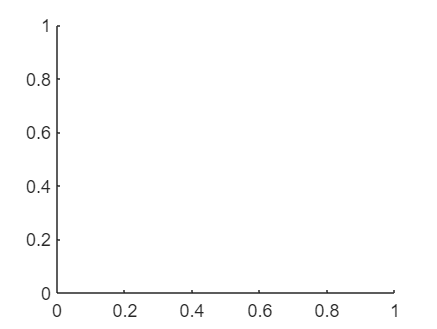


%Create Time variable 
hold off

x = 10/(10000-1);
y = idx*time_saved_resolution;
dTime = (0:x:y);

## Alkalinity map

image(dTime,depths,dtalkf,'CDataMapping','scaled')
title("Alkalinity [mol/m3]",[Seaweed Location])
xlabel("Time in years")
ylabel("Depth in m")
%caxis([2.5 7]);
%xlim([0 2.5])
xstart=append("Start ",Seaweed," addition");
xend=append("End ",Seaweed," addition");

x1=xline(a,'-w',{xstart})

x1 =   ConstantLine (Start Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 0.2667
            Color: [1 1 1]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: {'Start Macrocystis addition'}
      DisplayName: ''

  Show all properties


x2=xline(b,'-w',{xend})

x2 =   ConstantLine (End Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 1.1000
            Color: [1 1 1]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: {'End Macrocystis addition'}
      DisplayName: ''

  Show all properties


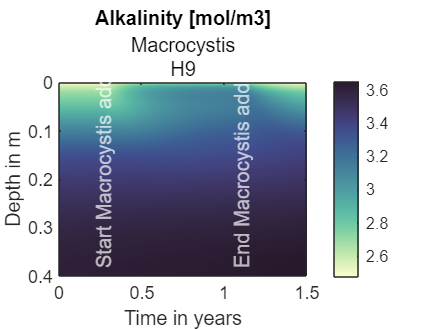

x1.LabelVerticalAlignment = 'bottom';
x1.LabelHorizontalAlignment = 'center';
x2.LabelVerticalAlignment = 'bottom';
x2.LabelHorizontalAlignment = 'center';

%colormap hsv
cmocean deep
colorbar

## Alkalinity graph

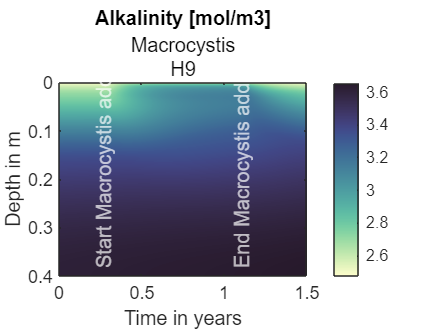

% Alkalinity plot
hold off

plot(dtalkf(:,1),-depths,'LineWidth',1.5)
title(Seaweed,['Alkalinity',Location])
xlabel("Alkalinity [mol/m3]")
ylabel('Depth [m]')
hold

Current plot held


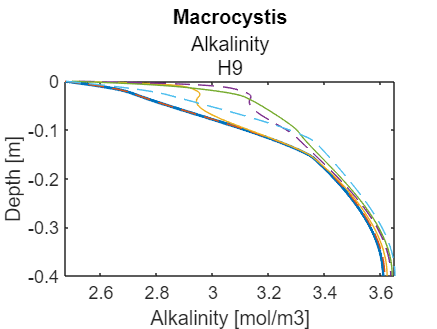

%plot(dtalkf(:,100),-depths,'--');
plot(dtalkf(:,200),-depths,'--');
%plot(dtalkf(:,300),-depths,'--');
plot(dtalkf(:,500),-depths);
plot(dtalkf(:,1000),-depths,'--');
plot(dtalkf(:,1200),-depths);
plot(dtalkf(:,1500),-depths,'--');

plot(dtalkf(:,2000),-depths);

Index in position 2 exceeds array bounds. Index must not exceed 1500.

%plot(dtalkf(:,2500),-depths);
plot(dtalkf(:,3000),-depths,'--');
%plot(dtalkf(:,4000),-depths,'--');
plot(dtalkf(:,5000),-depths,'LineWidth',1.5);
%plot(dtalkf(:,8000),-depths);
%plot(dtalkf(:,10000),-depths);

%xlim([2.5 6])
hold off
lgd = legend('0','0.2','0.5','1','1.2','1.5','2','3','5','Location','southwest');%,'5000','8000','10000','Location','southeast');
lgd.FontSize = 8;
title(lgd,'At t (yr)=')

hold off

## Oxygen and CO2 maps

image(dTime,depths,dO2f,'CDataMapping','scaled')
title(Seaweed,['Oxygen [mol/m3]' Location])
%caxis([0 0.01])
%xlim([0 2.5])
xlabel('Time in years')
ylabel('Depth in [m]')
x1=xline(a,'-y',{xstart},'LabelOrientation','Horizontal')

x1 =   ConstantLine (Start Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 0.2667
            Color: [1 1 0]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: {'Start Macrocystis addition'}
      DisplayName: ''

  Show all properties


x2=xline(b,'-w',{xend},'LabelOrientation','Horizontal')

x2 =   ConstantLine (End Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 1.1000
            Color: [1 1 1]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: {'End Macrocystis addition'}
      DisplayName: ''

  Show all properties


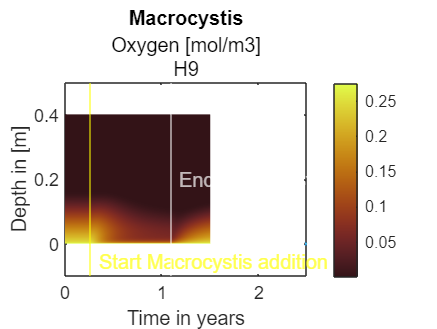

x1.LabelVerticalAlignment = 'bottom';
x1.LabelHorizontalAlignment = 'right';
x2.LabelVerticalAlignment = 'middle';
x2.LabelHorizontalAlignment = 'right';

%colormap hsv
cmocean solar
colorbar

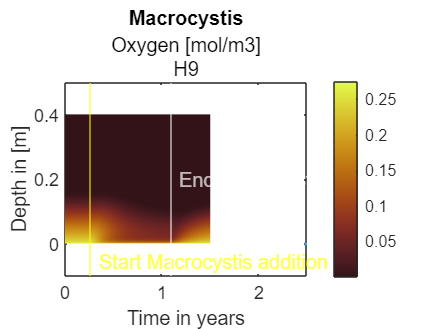

hold off

image(dTime,depths,dtCO2f,'CDataMapping','scaled')
title(Seaweed,['CO2 concentration [mol/m3]' Location])
%caxis([0 55])
%xlim([0 55])
xlabel('Time in years')
ylabel('Depth in [m]')
x1=xline(a,'--w',{xstart})

x1 =   ConstantLine (Start Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 0.2667
            Color: [1 1 1]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: {'Start Macrocystis addition'}
      DisplayName: ''

  Show all properties


x2=xline(b,'--w',{xend})

x2 =   ConstantLine (End Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 1.1000
            Color: [1 1 1]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: {'End Macrocystis addition'}
      DisplayName: ''

  Show all properties


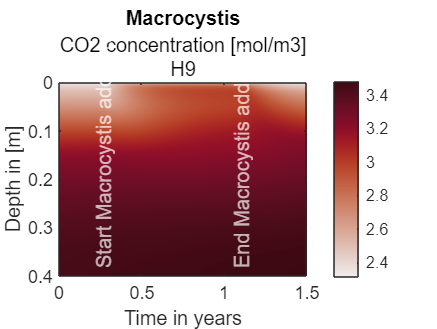

x1.LabelVerticalAlignment = 'bottom';
x1.LabelHorizontalAlignment = 'center';
x2.LabelVerticalAlignment = 'bottom';
x2.LabelHorizontalAlignment = 'center';
%colormap hsv
cmocean amp
colorbar

## Dissolved Ca and Calcite maps

hold off

image(dTime,depths,dCaf,'CDataMapping','scaled')
title(Seaweed,['Dissolved Calcium [mol/m3]' Location])
x1=xline(a,'--w',{xstart})

x1 =   ConstantLine (Start Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 0.2667
            Color: [1 1 1]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: {'Start Macrocystis addition'}
      DisplayName: ''

  Show all properties


x2=xline(b,'--w',{xend})

x2 =   ConstantLine (End Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 1.1000
            Color: [1 1 1]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: {'End Macrocystis addition'}
      DisplayName: ''

  Show all properties


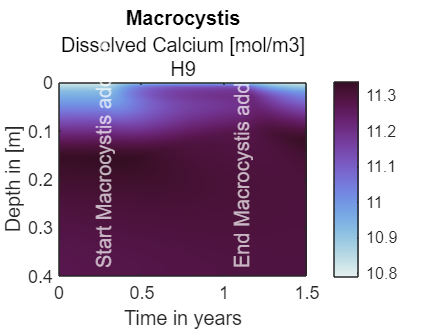

x1.LabelVerticalAlignment = 'bottom';
x1.LabelHorizontalAlignment = 'center';
x2.LabelVerticalAlignment = 'bottom';
x2.LabelHorizontalAlignment = 'center';
%xlim([0 2.5])
xlabel('Time in years')
ylabel('Depth in [m]')
%colormap winter
cmocean dense
%caxis([8 15])
colorbar

image(dTime,depths,pcalcitef,'CDataMapping','scaled')

title(Seaweed,['Calcite [mol/m3]' Location])
x1=xline(a,'--w',{xstart})

x1 =   ConstantLine (Start Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 0.2667
            Color: [1 1 1]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: {'Start Macrocystis addition'}
      DisplayName: ''

  Show all properties


x2=xline(b,'--w',{xend})

x2 =   ConstantLine (End Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 1.1000
            Color: [1 1 1]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: {'End Macrocystis addition'}
      DisplayName: ''

  Show all properties


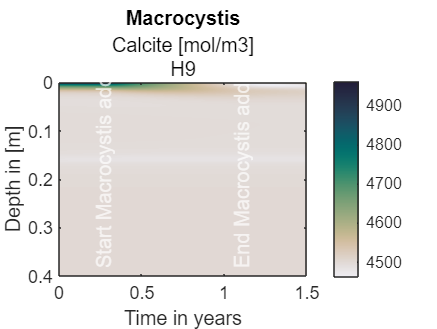

x1.LabelVerticalAlignment = 'bottom';
x1.LabelHorizontalAlignment = 'center';
x2.LabelVerticalAlignment = 'bottom';
x2.LabelHorizontalAlignment = 'center';
%xlim([0 2.5])
xlabel('Time in years')
ylabel('Depth in [m]')
%caxis([2000 5500])
%colormap turbo
cmocean rain
colorbar

## Clay map

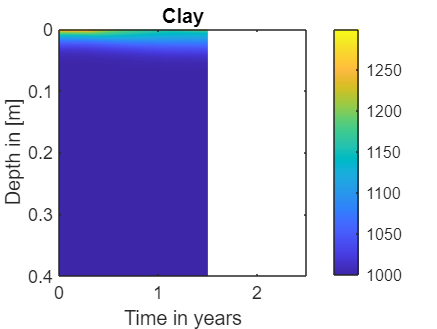

image(dTime,depths,pclayf,'CDataMapping','scaled')
title('Clay')
%xlim([0 2.5])
xlabel('Time in years')
ylabel('Depth in [m]')
colormap default
colorbar

## Organic carbon concentrations

image(dTime,depths,psocf,'CDataMapping','scaled')
title(Seaweed,['Background slow degrading carbon',Location])
%xlim([0 2.5])
x1=xline(a,'--r',{xstart},'LabelOrientation','Horizontal')

x1 =   ConstantLine (Start Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 0.2667
            Color: [1 0 0]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: {'Start Macrocystis addition'}
      DisplayName: ''

  Show all properties


x2=xline(b,'--r',{xend},'LabelOrientation','Horizontal')

x2 =   ConstantLine (End Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 1.1000
            Color: [1 0 0]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: {'End Macrocystis addition'}
      DisplayName: ''

  Show all properties


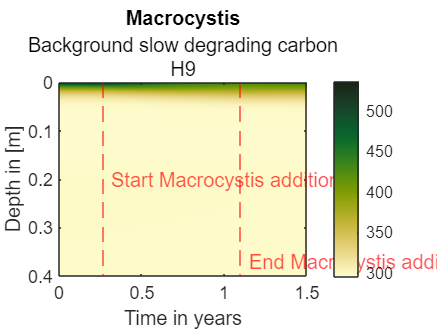

x1.LabelVerticalAlignment = 'middle';
x1.LabelHorizontalAlignment = 'right';
x2.LabelVerticalAlignment = 'bottom';
x2.LabelHorizontalAlignment = 'right';
xlabel('Time in years')
ylabel('Depth in [m]')
%colormap hsv
cmocean speed
colorbar

image(dTime,depths(1:50),pfocf(1:50,:),'CDataMapping','scaled')
title(Seaweed,['Background fast degrading carbon',Location])
%xlim([0 2.5])
x1=xline(a,'--r',{xstart},'LabelOrientation','Horizontal')

x1 =   ConstantLine (Start Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 0.2667
            Color: [1 0 0]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: {'Start Macrocystis addition'}
      DisplayName: ''

  Show all properties


x2=xline(b,'--r',{xend},'LabelOrientation','Horizontal')

x2 =   ConstantLine (End Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 1.1000
            Color: [1 0 0]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: {'End Macrocystis addition'}
      DisplayName: ''

  Show all properties


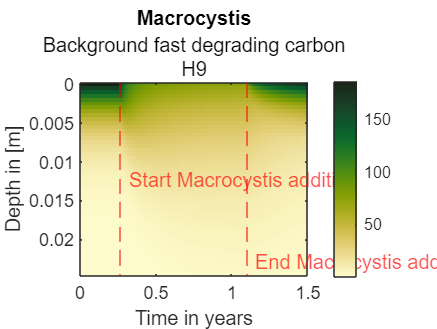

x1.LabelVerticalAlignment = 'middle';
x1.LabelHorizontalAlignment = 'right';
x2.LabelVerticalAlignment = 'bottom';
x2.LabelHorizontalAlignment = 'right';
%xlim([0 2.5])
xlabel('Time in years')
ylabel('Depth in [m]')
%colormap hsv
cmocean speed
colorbar

image(dTime,depths(1:50),pfocsf(1:50,:),'CDataMapping','scaled')
title(Seaweed,['Added slow degrading carbon',Location])
%xlim([0 2.5])
x1=xline(a,'--r',{xstart},'LabelOrientation','Horizontal')

x1 =   ConstantLine (Start Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 0.2667
            Color: [1 0 0]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: {'Start Macrocystis addition'}
      DisplayName: ''

  Show all properties


x2=xline(b,'--r',{xend},'LabelOrientation','Horizontal')

x2 =   ConstantLine (End Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 1.1000
            Color: [1 0 0]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: {'End Macrocystis addition'}
      DisplayName: ''

  Show all properties


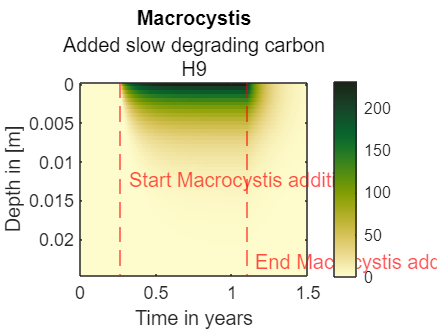

x1.LabelVerticalAlignment = 'middle';
x1.LabelHorizontalAlignment = 'right';
x2.LabelVerticalAlignment = 'bottom';
x2.LabelHorizontalAlignment = 'right';
%xlim([0 2.5])
xlabel('Time in years')
ylabel('Depth in [m]')
%colormap hsv
cmocean speed
colorbar

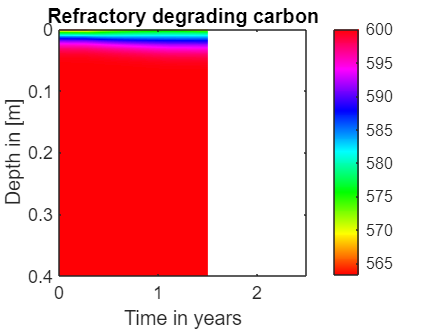

image(dTime,depths,procf,'CDataMapping','scaled')
title('Refractory degrading carbon')
xlim([0 2.5])
xlabel('Time in years')
ylabel('Depth in [m]')
colormap hsv
colorbar

image(dTime,depths,procsf,'CDataMapping','scaled')
title(Seaweed,['Added refractory degrading carbon [mol/m3]',Location])
%xlim([0 2.5])
x1=xline(a,'--r',{xstart})

x1 =   ConstantLine (Start Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 0.2667
            Color: [1 0 0]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: {'Start Macrocystis addition'}
      DisplayName: ''

  Show all properties


x2=xline(b,'--r',{xend})

x2 =   ConstantLine (End Macrocystis addition) with properties:

    InterceptAxis: 'x'
            Value: 1.1000
            Color: [1 0 0]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: {'End Macrocystis addition'}
      DisplayName: ''

  Show all properties


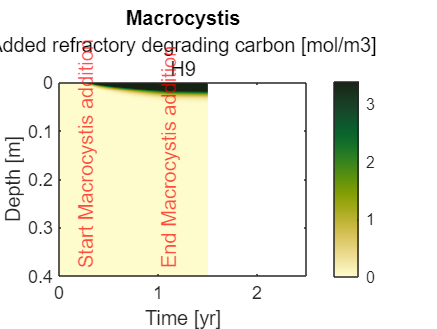

x1.LabelVerticalAlignment = 'bottom';
x1.LabelHorizontalAlignment = 'center';
x2.LabelVerticalAlignment = 'bottom';
x2.LabelHorizontalAlignment = 'center';
xlim([0 2.5])
xlabel('Time [yr]')
ylabel('Depth [m]')
caxis([0 3.4])
%colormap hsv
cmocean speed
colorbar

## Oxygen, DIC and alkalinity sediment interface fluxes

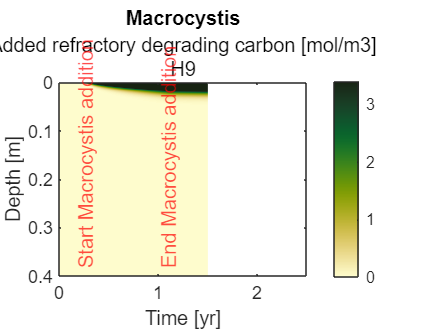

hold off

plot(dTime(1:2500),F_O2i(1:2500))

Index exceeds the number of array elements. Index must not exceed 1501.

hold
plot(dTime(1:2500),F_DICi(1:2500))
plot(dTime(1:2500),F_TAi(1:2500))

x1=xline(a,'--r',{xstart},'LabelOrientation','Horizontal')
x2=xline(b,'--k',{xend},'LabelOrientation','Horizontal')
x1.LabelVerticalAlignment = 'middle';
x1.LabelHorizontalAlignment = 'right';
x2.LabelVerticalAlignment = 'bottom';
x2.LabelHorizontalAlignment = 'right';
legend('O2','DIC','Alk')
xlabel('Time [yr]')
ylabel('Flux in [mol/m2]')
title(Seaweed,['Flux water-sediment interface',Location])
hold off

## Calculating diffusive fluxes over the sediment water interface

Change based on location

W2_DIC = 0.3252; % mol C/a
W2_O2 = -0.2067;% mol O2/a
W2_TA = 0.2988; % mol TA/a
H9_DIC = 0.2669; % mol C/a
H9_O2 = -0.1995;% mol O2/a
H9_TA = 0.2007; % mol TA/a
SM7_DIC = 0.2155; % mol C/a
SM7_O2 = -0.1452;% mol O2/a
SM7_TA = 0.1843; % mol TA/a

F_totDIC=sum(F_DICi(1:1000))/1000-1*H9_DIC

F_totO2=sum(F_O2i(1:1000))/1000-1*H9_O2

F_totTA=sum(F_TAi(1:1000))/1000-1*H9_TA

F_totDIC2=sum(F_DICi(1:2000))/1000-2*H9_DIC

F_totO22=sum(F_O2i(1:2000))/1000-2*H9_O2

F_totTA2=sum(F_TAi(1:2000))/1000-2*H9_TA

Fstot=(b-a)*Focs %total organic carbon added

